# 通信原理实验7

姓名：朱天昊

学号：18308267

邮箱：1312622783@qq.com

## 实验目标

`线性分组码、卷积码的编/译码实验。`

## 实验条件

MATLAB 2016 and above, Simulink, and Communications System Toolbox .

## Prelab

## 1 Hamming码、循环码、BCH码、RS码、CRC校验码的编译码原理

**Answer:**

**1）线性码、非线性码**

答：线性码：码字集中的元之间的任意线性组合仍是合法码字，编码器不带反馈电路的码就是线性码。

    非线性码：码元并不都是信息元的线性组合，可能还与前面已编的码元有关，编码器可能带反馈电路

**2）分组码、卷积码**

答：分组码：将信息序列每k个码元分为一组、编码和译码均按分组进行、编码器按一定规则依据每组信息位产生r个多余的码元称为校验位，构成长为n=k+r的码字。每个分组内的校验位仅与本组信息有关，组与组之间无记忆的码元就是分组码。

    卷积码：校验位不仅与本组信息有关，还与之前的组有关，组与组之间是有记忆的码元就是卷积码。

**3）检错码、纠错码**

答：检错码：发现信息序列差错的附加校验码元。

    纠错码：纠正信息序列部分差错的附加码元。

**4）Hamming码、循环码、BCH码、RS码、CRC校验码的编译码原理**

**答：**

Hamming码：

编码过程：统计信息位的位数k，令奇偶校验位的位数位r，要满足不等式 2*r>=r+k，总的码字位数位n（n=k+r).

1 给n位数据的数据位标上序号：1，2，3，4，5...

2 将这些数据位的位置序号转换为二进制：...000, ...001, ...010等

3 令数据位的位置序号中所有为2的幂次方的位是校验位，其他位置的数据位是信息位。

4 把每个校验码对应的各个信息位做异或运算，将得到的结果放入该校验位（校验位上的码字使得该校验位对应的信息组中”1“的个数为偶数），从而完成汉明码的编码。

译码过程：对汉明码进行检错。若每个校验位信息组的”1“的个数为偶数，则说明传输正确。这时可只取信息位，跳过校验位。

若信息组”1“的个数为奇数，则找到各错误信息组重叠的区间，该区间里的信息便是错误信息，将其取反便可继续传输。

循环码

编码过程：循环码的任一有效码组经循环移位后仍是有效码组。若它为（n,k)循环码，则可通过公式计算得到它的生成多项式g(x)。首先将信息码字表示为m(x)，其最高次幂为k-1;然后将x^(n-k)*m(x)与g(x)求模得出相应的余式r(x);最后得到它的编码结果c(x)=x^n(n-k)*m(x)+r(x)

译码过程：由接收码字R(x)与监督矩阵相乘得出错误图样S；然后判断S是否为零。若为零，则没有错误，可将码字R(x)直接输出；若不为零，则出错，将S与标准监督矩阵对比，得出错误的比特位并进行更正，最后输出更正后的码字。

BCH码

编码过程：构建码字为（c12,c13,...c8),这样多项式为c14+c13+...+c8，我们将它称为C1。然后就要找出Cr使它满足Cr=C1+Cr(mod(m(x))=0.

译码过程：首先计算接收到的码字向量R的2t伴随矩阵；计算错误定位多项式；解该多项式，便可得到错误位置。最后对错误位置的码元进行修正，便可输出码字。

RS码

编码过程；判断码元符号来自哪个域，判断需要有几个比特来表示一个码元，得到其x*d(x)和g(x)的二进制表示。计算x*d(x)/g(x)得到余式r(x)的二进制比特表式，将其转化为多进制，从而得到校验位，将校验位加到信息位后面，便可完成编码。

译码过程：由接收多项式计算伴随式；用BM算法或Euclid算法通过伴随式求出错误位置多项式；再用Chien搜索法求伴随式的根，其倒数为错误位置数，计算错误值。将接收多项式减去错误多项式，便可实现纠错，完成译码。

CRC校验码

编码过程：先选择一个用于在接收端进行校验时，对接收的帧进行除法运算的除数。看所选定的除数二进制位数，然后在要发送的数据帧后面加上k-1位‘0’，以这个加了k-1个“0”的新帧以“模2除法”方式除以上面这个除数，所得到的余数就是该帧的CRC校验码，最后把这个校验码附加在原数据帧上，便可实现编码。

译码过程：将接收的n位码用信息位和校验位按位进行异或，得到一个k位的合成码；再利用合成码产生一个校验码。若信息位中有奇数个“1”，则合成码即为校验码，否则合成码的反码为校验码。最后通过校验码中“1”的个数进行判决和纠错，便可实现译码。

## **2 Hamming码编译码实现**

1）仿真（7,4）Hamming码的编码及硬判决译码过程。

2）仿真未编码和进行（7,4）Hamming码的编码的QPSK调制通过AWGN信道后的误比特性能比较。

% insert your code here
clc; close all; clear all

% （1）仿真（7，4）Hamming码的编码及硬判决译码过程
N = 10;                       % 信息比特码组数
n = 7;                        % Hamming码组长度n=2^m-1
r = 3;                        % 校验位长度
[H,G] = hammgen(r);           % 产生一个(n,n-r)Hamming码的校验矩阵H和生成矩阵G
msg = randi([0,1],N,n-r);     %产生比特数据矩阵，每一行为一个码组，一个码组有n-r个比特
msg_ham = mod(msg*G, 2);       %Hamming编码,生成码字
msg_ham1 = mod(msg_ham+randerr(N,n),2);    %在每一个编码码组中引入一个随机比特错误
mat1 = eye(n);                %生成n*n的单位矩阵，其中每一行的1代表错误比特位置
errvec = mat1*H';             %校验结果对应的所有错误矢量，得到差错图样
msg_ham2 = mod(msg_ham1*H',2);             %通过校验矩阵H译码
%根据译码结果对应的错误矢量找出错误比特位置，并纠错
for i = 1:N
    for index1 = 1:n
        if(msg_ham2(i,:) == errvec(index1,:))
            msg_ham1(i,:) = mod(msg_ham1(i,:)+mat1(index1,:),2);
        end
    end
end
msg_dec = msg_ham1(:,r+1:end);         %恢复原始信息比特
if msg_dec == msg
    disp('信息恢复成功');
else
    disp('信息恢复失败');
end

信息恢复成功


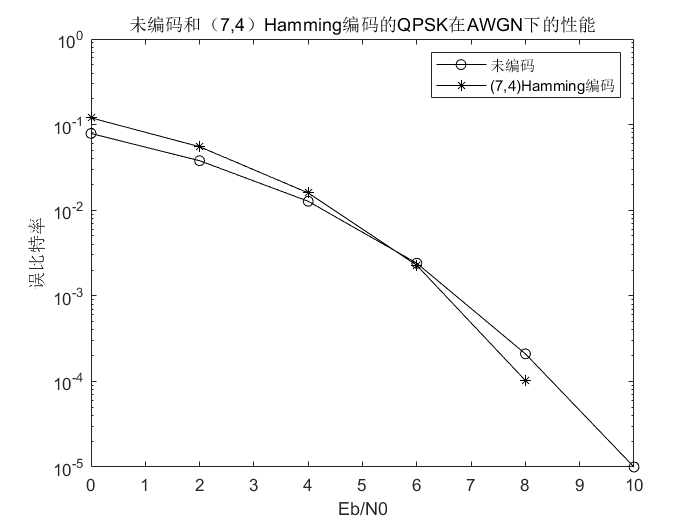


% （2）仿真未编码和进行（7,4）Hamming码的编码的QPSK调制通过AWGN信道后的误比特性能比较。
clear all
nbit = 100000;       % 信息序列码组数
n = 7;              % 码组长度
r = 3;              % 校验位长度
graycode = [0, 1, 3, 2];
M = length(graycode);
msg = randi([0,1], nbit, n-r) ;

% 信噪比范围
EbN0 = 0:2:10;
EbN0_lin = 10.^(EbN0/10);

% 对照组：未编码的QPSK调制
msg1 = reshape(msg.', log2(M), nbit*(n-r)/log2(M)).';
msg1_dec = bi2de(msg1, 'left-msb');
msg1 = graycode(msg1_dec+1);
msg1 = pskmod(msg1, M);     % QPSK调制
Eb1 = norm(msg1).^2/(nbit*(n-r));
for i = 1:length(EbN0_lin)
    sigma1 = sqrt(Eb1/(2*EbN0_lin(i)));
    rx1 = msg1+sigma1*(randn(1,length(msg1))+1j*randn(1,length(msg1)));
    y1 = pskdemod(rx1, M);  % 解调
    y1_de = graycode(y1+1);
    [err, ber1(i)] = biterr(msg1_dec.', y1_de, log2(M));
end

% 实验组：（7,4）Hamming码编码的QPSK调制
msg2 = encode(msg, n, n-r);
msg2 = reshape(msg2.', log2(M), nbit*n/log2(M)).';
msg2 = bi2de(msg2, 'left-msb');
msg2 = graycode(msg2+1);
msg2 = pskmod(msg2, M);     % QPSK调制
Eb2 = norm(msg2).^2/(nbit*(n-r));
for i = 1:length(EbN0_lin)
    sigma2 = sqrt(Eb2/(2*EbN0_lin(i)));
    rx2 = msg2+sigma2*(randn(1,length(msg2))+1j*randn(1,length(msg2)));    % 加入高斯白噪声
    y2 = pskdemod(rx2, M);  % 解调
    y2 = graycode(y2+1);
    y2 = de2bi(y2, 'left-msb');
    y2 = reshape(y2.', n, nbit).';
    y2 = decode(y2, n, n-r);
    [err, ber2(i)] = biterr(msg, y2);
end

% 画图
semilogy(EbN0, ber1, '-ko', EbN0, ber2, '-k*');
legend('未编码', '(7,4)Hamming编码');
title('未编码和（7,4）Hamming编码的QPSK在AWGN下的性能');
xlabel('Eb/N0'); ylabel('误比特率');

## 3 卷积码的编译码原理

**Answer:**

答：卷积码的编译码原理：

编码方法：将信息序列分隔成长度k的一个个分组，令莫一时刻的编码输出不仅取决于本时刻的分组，还取决于本时刻以前的L个分组。

首先使用串并转换器将串行信息序列进行并行传输，存入有k个L+1级寄存器构成的k*(L+1)阵列；再通过线性组合器对阵列中的数据进行组合编码，在对编好的码元进行并串转换，方可得到卷积码序列。

译码方法：采用维特比译码算法：对接收到的码字分段处理。每接收到一段码字，计算、比较一次累积的汉明距离，保留码距最小的路径，直至译完整个序列。

## Lab

**仿真BPSK调制在AWGN信道下分别使用卷积码和未使用卷积码的性能对比，其中，卷积码的约束长度为7，生成多项式为[171,133]，码率为1/2，译码分别采用硬判决译码和软判决译码。**

**Answer:**

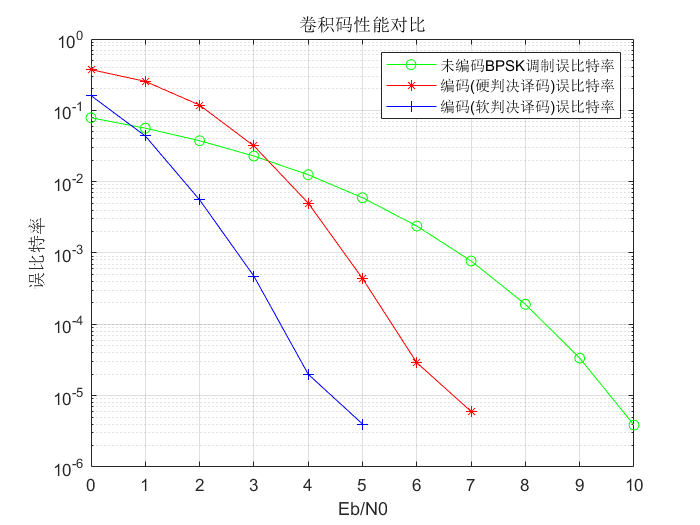

% insert your code here
clc; close all; clear all；
EbN0 = 0:10;      % Eb/N0  的范围  
nbit = 1000000;   % 消息比特数  
M = 2;            % 调制阶数(BPSK调制)  
L = 7;            % 约束长度  
msg = randi([0,1], 1, nbit);   % 随机生成1000000个信息比特


trel=poly2trellis(L,[171,133]);     % 卷积码生成多项式  
tblen=6*L;                          % Viterbi译码器回溯深度  
msg2=convenc(msg,trel);             % 1/2卷积编码  
x=pskmod(msg2,M);                   % BPSK调制  
  
for snr = 1:length(EbN0)   
    % 加入AWGN，因为码率为1/2，根据SNR与EbN0的公式关系，得：SNR=Ebn0-3 (awgn函数的输入参数必须为SNR）
    y=awgn(x, EbN0(snr)-3);  
    y1=pskdemod(y,M);                                         % 硬判决  
    y1=vitdec(y1,trel,tblen,'cont','hard');                   % Veterbi译码  
    [err,ber1(snr)]=biterr(y1(tblen+1:end),msg(1:end-tblen)); % 计算误比特率  
     
    y2=vitdec(real(y),trel,tblen,'cont','unquant');           % 软判决  
    [err,ber2(snr)]=biterr(y2(tblen+1:end),msg(1:end-tblen)); % 计算误比特率  
end  
  
ber=berawgn(EbN0,'psk',2,'nodiff');     		              % 未编码BPSK调制误比特率  
semilogy(EbN0,ber,'-go',EbN0,ber1,'-r*',EbN0,ber2,'-b+');  
legend('未编码BPSK调制误比特率','编码(硬判决译码)误比特率','编码(软判决译码)误比特率')
grid on;  
title('卷积码性能对比')  
xlabel('Eb/N0');ylabel('误比特率')

**仿真结果分析：**

1）卷积码与线性分组码相比，将有限个信息码元序列组前后间的关系添加到码字里面，防止信息流割裂为孤立块后丧失分组间的相关信息。这样一来可以减小信息码元序列组长度，也减少了码组接收时的译码时间，更加适合串行传输场景。

2）通过卷积码性能对比图可以发现，当比特信噪比Eb/N0数值较小时，未编码的BPSK调制误比特率比编码后的误比特率小。但随着Eb/N0的增加，使用卷积码编码的误比特率变得更小。这是因为在小信噪比情况下，编码的纠错能力超过了纠错门限以至于纠错码不再纠错，反而造成了更多的错误；而在大信噪比的情况下，由于卷积码可实现短码长下的纠错，所以误比特率更低。

3）由性能对比图还可以发现，软判决译码的误比特率总是比硬判决的要低。这是因为维特比译码的软判决算法与硬判决算法相比，软判决译码算法的路径度量采用欧几里得距离而非汉明距离。在采用软距离的情况下，路径度量为模拟值，需经过一些处理以便于相加和比较。因此，计算复杂度有所提高。而硬判决译码的判决过程损失了信道信息，所以性能不如软判决。

## 实验总结

通过这次实验，我掌握了线性分组码和卷积码的信道编译码原理。这两种码元都具备纠错检错能力，在信噪比足够大的情况下都可有效降低误比特率。线性分组码的编码只取决于当前信息组，分组码长n较大；而卷积码的编码不仅取决于当前信息组，还与前L个信息组有关，充分利用了码组之间的关系，有效缩短了码长。在编码器复杂性相同的情况下，卷积码的性能要优于分组码。